# Problema 6

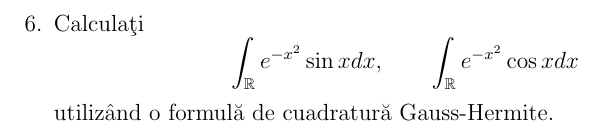

% PB1
function [noduri, coeficienti] = gauss_hermite(n)
    alpha = zeros(n, 1);
    beta = sqrt((1:n-1) / 2)';
    beta0 = sqrt(pi);

    J = diag(alpha) + diag(beta, 1) + diag(beta, -1);
    [V, D] = eig(J);
    noduri = diag(D);
    [noduri, ord] = sort(noduri);
    V = V(:, ord);
    coeficienti = beta0 * V(1,:).^2;
end

function [I, eroare] = integrare_hermite(f, n, valoare_exacta)
% Input:
%   f              - functia f(x) (fara ponderea e^{-x^2})
%   n              - numarul de noduri
%   valoare_exacta - valoare reala de referinta pentru comparatie (optional)
%
% Output:
%   I      - valoare aproximata a integralei
%   eroare - eroare absoluta (daca se furnizeaza valoarea exacta)

    if nargin < 3
        valoare_exacta = NaN;
    end

    [x, A] = gauss_hermite(n);  % folosim generatorul standard

    I = sum(A .* f(x));

    if isnan(valoare_exacta)
        eroare = NaN;
    else
        eroare = abs(I - valoare_exacta);
    end
end

n = 20;

% f(x) = sin(x)
f1 = @(x) sin(x);
exact1 = 0;  % integrala functiei impare pe R => 0

% f(x) = cos(x)
f2 = @(x) cos(x);
exact2 = sqrt(pi) * exp(-1/4);

[I1, err1] = integrare_hermite(f1, n, exact1);
[I2, err2] = integrare_hermite(f2, n, exact2);

fprintf(" Cuadratura Gauss-Hermite (n = %d)\n", n);

 Cuadratura Gauss-Hermite (n = 20)


fprintf("→ ∫ e^{-x^2} sin(x) dx ≈ %.10f   | eroare: %.2e\n", I1, err1);

→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 9.82e-25
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 1.78e-20
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 6.94e-18
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 2.50e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 8.33e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 7.77e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 2.78e-17
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 4.61e-19
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 1.99e-22
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 5.30e-28
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 9.82e-25
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 1.78e-20
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 6.94e-18
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 2.50e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 8.33e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 7.77e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 2.78e-

fprintf("→ ∫ e^{-x^2} cos(x) dx ≈ %.10f   | eroare: %.2e\n", I2, err2);

→ ∫ e^{-x^2} cos(x) dx ≈ -0.0000000000   | eroare: -7.51e-10
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0000001854   | eroare: -1.33e-05
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0003897937   | eroare: -5.54e-03
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0423536907   | eroare: -1.86e-01
→ ∫ e^{-x^2} cos(x) dx ≈ -0.4893797169   | eroare: -7.89e-01
→ ∫ e^{-x^2} cos(x) dx ≈ -0.7890896568   | eroare: -4.89e-01
→ ∫ e^{-x^2} cos(x) dx ≈ -0.1861017367   | eroare: -4.24e-02
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0055373998   | eroare: -3.90e-04
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0000133196   | eroare: -1.85e-07
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0000000008   | eroare: -3.81e-13
→ ∫ e^{-x^2} cos(x) dx ≈ 1.3803884470   | eroare: 1.38e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.3803886324   | eroare: 1.38e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.3807782407   | eroare: 1.39e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.4227421377   | eroare: 1.57e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.8697681639   | eroare: 2.17e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 2.1694781039   | eroare: 1.87e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.566490183